# PINN-based temperature distribution inversion

clc,clear
close all

## load simulation data


load("STrain5.mat"); load("STest5.mat");
load("BTrain5.mat"); load("BTest5.mat");
load("num5.mat");

load("mu.mat");
load("sigma.mat");

% the following code is used to calculate the mu and sigma
% ZS = [];
% ZS = [ZS;STrain.train1;STrain.train2;STrain.train3;STrain.train4;STrain.train5;STrain.train6;STrain.train7;STrain.train8;...
%     STrain.train9;STrain.train10;STrain.train11;STrain.train12;STrain.train13;STrain.train14;STrain.train15;STrain.train16;...
%     STrain.train17;STrain.train18;STrain.train19;STrain.train20;STrain.train21;STrain.train22;STrain.train23;STrain.train24;...
%     STrain.train25;STrain.train26;STrain.train27;STrain.train28;STrain.train29;STrain.train30;STrain.train31;STrain.train32;...
%     STrain.train33;STrain.train34;STrain.train35;STrain.train36;STrain.train37;STrain.train38;STrain.train39;STrain.train40;...
%     STrain.train41];
% ZX1 = ZS(:,1:2); ZY1 = ZS(:,3:7); ZZ1 = ZS(:,8);
% 
% [~,mu.ZX1,sigma.ZX1] = zscore(ZX1);
% [~,mu.ZY1,sigma.ZY1] = zscore(ZY1);
% [~,mu.ZZ1,sigma.ZZ1] = zscore(ZZ1);
% 
% ZB = [];
% ZB = [ZB;BTrain.train1;BTrain.train2;BTrain.train3;BTrain.train4;BTrain.train5;BTrain.train6;BTrain.train7;BTrain.train8;...
%     BTrain.train9;BTrain.train10;BTrain.train11;BTrain.train12;BTrain.train13;BTrain.train14;BTrain.train15;BTrain.train16;...
%     BTrain.train17;BTrain.train18;BTrain.train19;BTrain.train20;BTrain.train21;BTrain.train22;BTrain.train23;BTrain.train24;...
%     BTrain.train25;BTrain.train26;BTrain.train27;BTrain.train28;BTrain.train29;BTrain.train30;BTrain.train31;BTrain.train32;...
%     BTrain.train33;BTrain.train34;BTrain.train35;BTrain.train36;BTrain.train37;BTrain.train38;BTrain.train39;BTrain.train40;...
%     BTrain.train41];
% ZX2 = ZB(:,1:2); ZY2 = ZB(:,3:7); ZZ2 = ZB(:,8);
% [~,mu.ZX2,sigma.ZX2] = zscore(ZX2);
% [~,mu.ZY2,sigma.ZY2] = zscore(ZY2);
% [~,mu.ZZ2,sigma.ZZ2] = zscore(ZZ2);
% ----------------------------------------------------------------

TrainFields = fieldnames(STrain);

len = length(TrainFields);

## Build NN

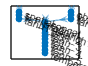

numObservations = 5;  % observable temperatures
numSpatial = 2;       % spatial lables

branch1 = [
    featureInputLayer(numSpatial,Name="spatial")
    fullyConnectedLayer(512,Name="fc1_branch1") % 256
    tanhLayer('Name','tanh1_branch1')
    ];

branch2 = [
    featureInputLayer(numObservations,Name="observation")
    fullyConnectedLayer(512,Name="fc1_branch2") % 256
    tanhLayer('Name','tanh1_branch2')
    ];

mergedLayers = [
    concatenationLayer(1,2,Name="concat")
    fullyConnectedLayer(512,'Name',"fc2") % 256
    tanhLayer(Name="tanh_2")
    fullyConnectedLayer(256,'Name',"fc3") % 128
    tanhLayer(Name="tanh_3")
    fullyConnectedLayer(128,'Name',"fc4") % 64
    tanhLayer(Name="tanh_4")
    fullyConnectedLayer(64,'Name',"fc5") % 32
    tanhLayer(Name="tanh_5")

    fullyConnectedLayer(1,Name="temperature")
    ];

layers = layerGraph(branch1);
layers = addLayers(layers, branch2);
layers = addLayers(layers,mergedLayers);

layers = connectLayers(layers, 'tanh1_branch1', 'concat/in1');
layers = connectLayers(layers, 'tanh1_branch2', 'concat/in2');

pinn = dlnetwork(layers);

pinn = initialize(pinn);

figure
plot(pinn)

## **Specify Training Options**

Specify the number of epochs, mini-batch size, initial learning rate, and the learning rate decay.

numEpochs = 100;
miniBatchSize1 = 1080*2;
miniBatchSize2 = 460*2;
initialLearnRate = 0.001; % previous value is 0.0001
learnRateDecay = 0.1; % previous value is 0.6 / latest one is 0.9
decayStep = 8000; % previous value is 3000 / latest one is 5000
L_threshold = 1e-3;

Convert the training data to [`dlarray`](https://ww2.mathworks.cn/help/deeplearning/ref/dlarray.html) (Deep Learning Toolbox) objects.

TX1 = (STest(:,1:2) - mu.ZX1) ./ sigma.ZX1;
TY1 = (STest(:,3:7) - mu.ZY1) ./ sigma.ZY1;
TZ1 = STest(:,8);
Tspatial1 = dlarray(TX1,"BC");
Tobservation1 = dlarray(TY1,"BC");
Y_test1 = dlarray(TZ1,"BC");

TX2 = (BTest(:,1:2) - mu.ZX2) ./ sigma.ZX2;
TY2 = (BTest(:,3:7) - mu.ZY2) ./ sigma.ZY2;
TZ2 = BTest(:,8);
Tspatial2 = dlarray(TX2,"BC");
Tobservation2 = dlarray(TY2,"BC");
Y_test2 = dlarray(TZ2,"BC");

Initialize the average gradients and squared average gradients.

averageGrad = [];
averageSqGrad = [];

Calculate the total number of iterations for the training progress monitor.

numIterations = numEpochs*num;

Initialize the [`trainingProgressMonitor`](https://ww2.mathworks.cn/help/deeplearning/ref/deep.trainingprogressmonitor.html) (Deep Learning Toolbox) object.

monitor = trainingProgressMonitor;
monitor.Metrics = ["TrainingLoss","SmoothedLoss","ValidationLoss"];
windowSize = 50;
monitor.XLabel = "Iteration";
groupSubPlot(monitor,"Loss",["TrainingLoss","SmoothedLoss"]);
monitor.Info = ["LearningRate","Epoch","Iteration","ExecutionEnvironment",...
    "TrainingLoss","ValidationLoss"];
monitor.Status = "Configuring";
monitor.Progress = 0;
% select the execution environment and record this information in the
% training progress monitor using updateInfo
executionEnvironment = "auto";

if (executionEnvironment == "auto" && canUseGPU) || executionEnvironment == "gpu"
    updateInfo(monitor,ExecutionEnvironment="GPU");
else
    updateInfo(monitor,ExecutionEnvironment="CPU");
end

## **Train PINN**

Train the model using a custom training loop. Update the network parameters using the [`adamupdate`](https://ww2.mathworks.cn/help/deeplearning/ref/adamupdate.html) (Deep Learning Toolbox) function. At the end of each iteration, display the training progress.

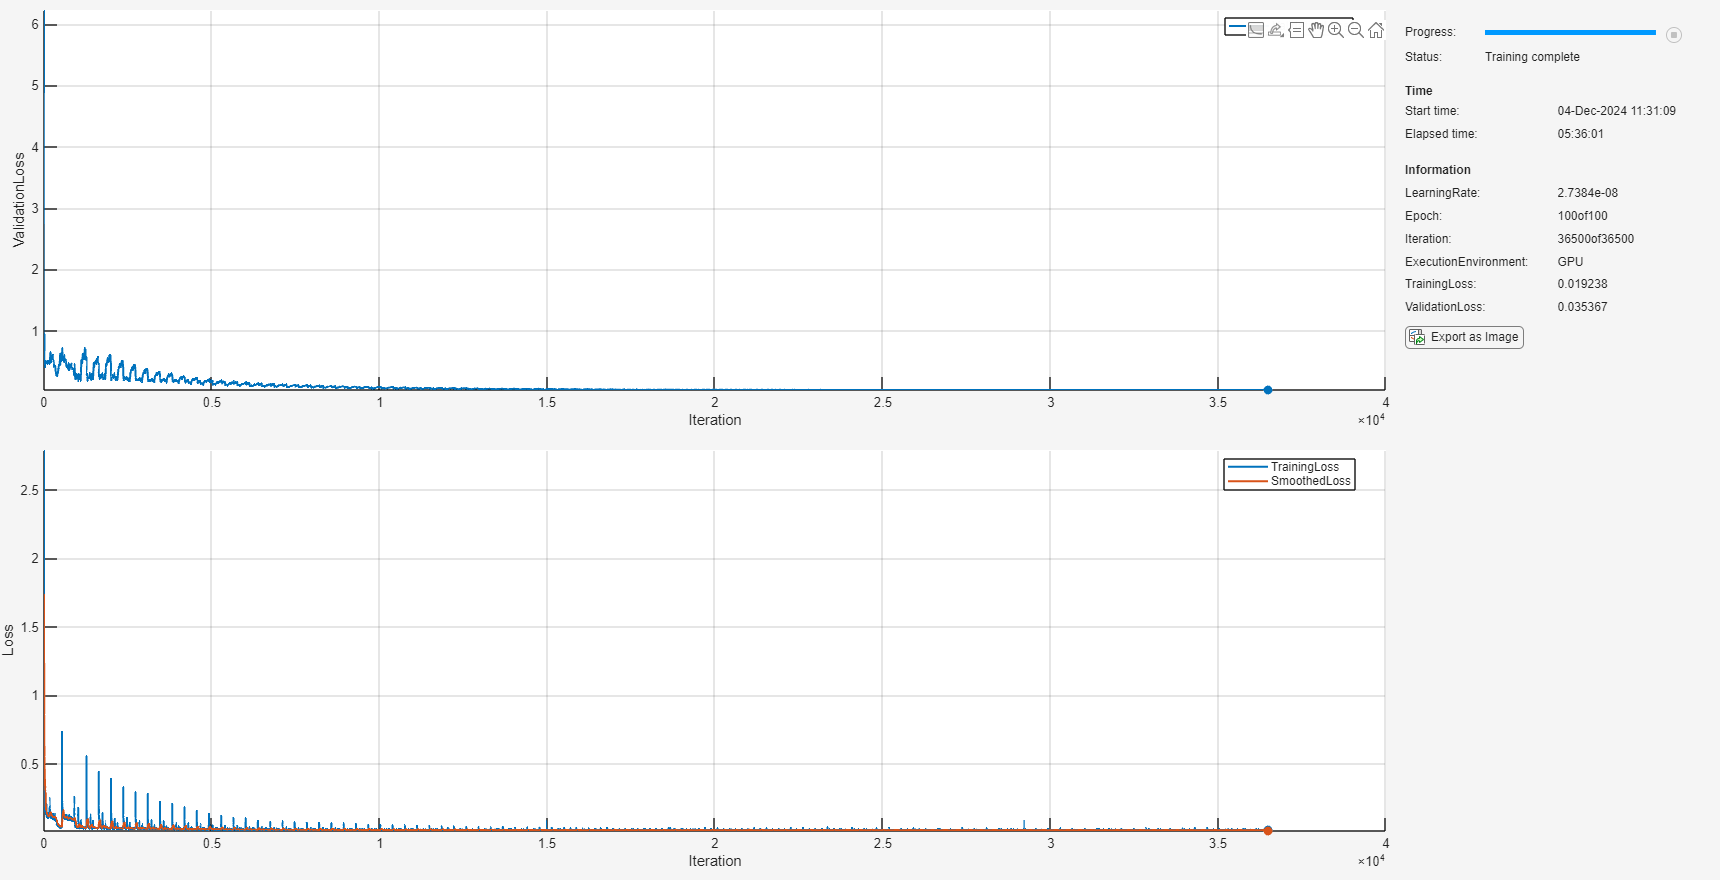

monitor =   TrainingProgressMonitor with properties:

       Metrics: ["TrainingLoss"    "SmoothedLoss"    "ValidationLoss"]
          Info: ["LearningRate"    "Epoch"    "Iteration"    "ExecutionEnvironment"    "TrainingLoss"    "ValidationLoss"]
        XLabel: "Iteration"
        Status: "Training complete"
      Progress: 100
          Stop: 0
    MetricData: [1×1 struct]
      InfoData: [1×1 struct]
       Visible: on

iteration = 0;
epoch = 0;
learningRate = initialLearnRate;
lossArray = [];
smoothedLossArray = [];

renum = 1;

monitor.Status = "Running";

vloss = 1000;

while epoch < numEpochs && ~monitor.Stop && vloss>L_threshold
    epoch = epoch + 1;

    for i = 1:len
        Sdata = STrain.(TrainFields{i});
        Bdata = BTrain.(TrainFields{i});
        XX1 = Sdata(:,1:7); YY1 = Sdata(:,8); ZZ1 = Sdata(:,9); 
        TT1 = Sdata(:,10:13);

        XX2 = Bdata(:,1:7); YY2 = Bdata(:,8);

        idx1 = randperm(size(XX1,1));
        X_train1 = XX1(idx1,:);
        Y_train1 = YY1(idx1,:);
        Z_train1 = ZZ1(idx1,:);
        V_train1 = TT1(idx1,:);
        dsTrain1 = arrayDatastore(X_train1);
        dsLabel1 = arrayDatastore(Y_train1);
        dsValue1 = arrayDatastore(Z_train1);
        dsTem1 = arrayDatastore(V_train1);
        dsTrainCombined1 = combine(dsTrain1,dsLabel1,dsValue1,dsTem1);
        mbq1 = minibatchqueue(dsTrainCombined1,...
            MiniBatchSize=miniBatchSize1, ...
            MiniBatchFormat="BC");
    
        idx2 = randperm(size(XX2,1));
        X_train2 = XX2(idx2,:);
        Y_train2 = YY2(idx2,:);
        dsTrain2 = arrayDatastore(X_train2);
        dsLabel2 = arrayDatastore(Y_train2);
        dsTrainCombined2 = combine(dsTrain2,dsLabel2);
        mbq2 = minibatchqueue(dsTrainCombined2,...
            MiniBatchSize=miniBatchSize2, ...
            MiniBatchFormat="BC");

        while hasdata(mbq1) && hasdata(mbq2) && ~monitor.Stop && vloss>L_threshold
            iteration = iteration + 1;
            [X1,Y1,V,T] = next(mbq1);
            [X2,Y2] = next(mbq2);

            lambada = 0.01;

            % Evaluate the model loss and gradients using dlfeval.
            [loss,gradients,lossF,lossD,lossB] = dlfeval(@modelLoss,pinn,X1,Y1,V,T,X2,Y2,lambada,mu,sigma);
            % determine learning rate for time-based decay learning rate
            L.tl(iteration) = loss;
            L.lf(iteration) = lossF;
            L.ld(iteration) = lossD;
            L.lb(iteration) = lossB;

            lossArray = [lossArray;double(loss)];

            if length(lossArray) >= windowSize
                smoothedLoss = mean(lossArray(end-windowSize+1:end));
            else
                smoothedLoss = mean(lossArray);
            end

            smoothedLossArray = [smoothedLossArray; smoothedLoss];

            learningRate = initialLearnRate * learnRateDecay^(iteration/decayStep);

            % Update the network parameters using the adamupdate function.
            [pinn,averageGrad,averageSqGrad] = ...
                adamupdate(pinn,gradients,averageGrad, ...
                averageSqGrad,iteration,learningRate);

            % Record training loss
            recordMetrics(monitor,iteration,...
                TrainingLoss = loss);

            recordMetrics(monitor,iteration,...
                SmoothedLoss=smoothedLoss);

            % Record validation loss
            if iteration == 1 || ~hasdata(mbq1) || ~hasdata(mbq2)

                pred1 = predict(pinn,Tspatial1,Tobservation1);
                pred2 = predict(pinn,Tspatial2,Tobservation2);
                pred1 = pred1 .* sigma.ZZ1 + mu.ZZ1;
                pred2 = pred2 .* sigma.ZZ2 + mu.ZZ2;

                loss1 = mse(pred1,Y_test1);
                loss2 = mse(pred2,Y_test2);
                vloss = 0.8*loss1+0.2*loss2; % 1002 BEST

                L.iteration(renum) = iteration;
                L.loss1(renum) = loss1;
                L.loss2(renum) = loss2;
                L.vloss(renum) = vloss;

                renum = renum+1;

                recordMetrics(monitor,iteration,...
                    ValidationLoss=vloss);
            end


            if iteration == 300
                save('trainedNetwork1204_300.mat','pinn');
            end

            if iteration == 3000
                save('trainedNetwork1204_3k.mat','pinn');
            end

            if iteration == 30000
                save('trainedNetwork1204_30k.mat','pinn');
            end

            % update learning rate, epoch, and iteration information values
            updateInfo(monitor,...
                LearningRate = learningRate,...
                Epoch = string(epoch) + "of" + string(numEpochs),...
                Iteration = string(iteration) + "of" + string(numIterations),...
                TrainingLoss = loss,...
                ValidationLoss = vloss);

            % update progress percentage
            monitor.Progress = 100 * iteration/numIterations;

        end

    end

end

% update the training status
if monitor.Stop == 1
    monitor.Status = "Training stopped";
else
    monitor.Status = "Training complete"
end

save net and some data


% save('Loss1018.mat','L');
% 
% save('trainedNetwork1018.mat','pinn');
% 
% save('smoothedLoss1018.mat','smoothedLossArray');

## **Model Loss Function**

The `modelLoss` helper function takes as inputs a `dlnetwork` object `pinn` and a mini-batch of input data `XY`.

function [loss,gradients,lossF,lossD,lossB] = modelLoss(net,X1,Y1,V,T,X2,Y2,lambada,mu,sigma)

dim = 2;

spatial1 = X1(1:2,:);

observation1 = X1(3:7,:);

% Ensure sigma and mu are broadcastable to match spatial1 size
Spa1_sigma = reshape(sigma.ZX1, 2, 1);  % Reshape to 2x1
Spa1_mu = reshape(mu.ZX1, 2, 1);        % Reshape to 2x1
Spa1 = (spatial1 - Spa1_mu) ./ Spa1_sigma;

Ob1_sigma = reshape(sigma.ZY1, 5, 1);  % Reshape to 2x1
Ob1_mu = reshape(mu.ZY1, 5, 1);        % Reshape to 2x1
Ob1 = (observation1 - Ob1_mu) ./ Ob1_sigma;

[U1,~] = forward(net,Spa1,Ob1);

Y1 = (Y1 - mu.ZZ1) ./ sigma.ZZ1;

lossD = mse(U1,Y1);

U1 = U1.*sigma.ZZ1 + mu.ZZ1;

% lossD = mse(U1,Y1);

% Compute gradients of U and Laplacian of U.
gradU = dlgradient(sum(U1,"all"),spatial1,EnableHigherDerivatives=true);
Laplacian = 0;
for i=1:dim
    gradU2 = dlgradient(sum(gradU(i,:),"all"), ...
                          spatial1,EnableHigherDerivatives=true);
    Laplacian = gradU2(i,:)+Laplacian;
end

gradUT = dlgradient(sum(U1,"all"),observation1,EnableHigherDerivatives=true);
deltaT = 0;
for j = 1:4
    deltaT = deltaT + T(j,:).*gradUT(j,:);
end
deltaT = deltaT./4;

% Enforce PDE. Calculate lossF.
% res = V - 0.025*Laplacian;
res = 1.225 * 1005 .*deltaT - 0.025.*Laplacian;
zeroTarget = zeros(size(res),"like",res);
lossF = mse(res,zeroTarget);

spatial2 = X2(1:2,:);

observation2 = X2(3:7,:);

% Ensure sigma and mu are broadcastable to match spatial1 size
Spa2_sigma = reshape(sigma.ZX2, 2, 1);  % Reshape to 2x1
Spa2_mu = reshape(mu.ZX2, 2, 1);        % Reshape to 2x1
Spa2 = (spatial2 - Spa2_mu) ./ Spa2_sigma;

Ob2_sigma = reshape(sigma.ZY2, 5, 1);  % Reshape to 2x1
Ob2_mu = reshape(mu.ZY2, 5, 1);        % Reshape to 2x1
Ob2 = (observation2 - Ob2_mu) ./ Ob2_sigma;

[U2,~] = forward(net,Spa2,Ob2);

Y2 = (Y2 - mu.ZZ2) ./ sigma.ZZ2;

lossB = mse(Y2,U2);

U2 = U2.*sigma.ZZ2 + mu.ZZ2;

% lossB = mse(Y2,U2);

% loss = lambada*lossF+0.8*lossD+0.2*lossB;
loss = lambada*lossF+0.8*lossD+0.2*lossB;


% Calculate gradients with respect to the learnable parameters.
gradients = dlgradient(loss,net.Learnables); 
end
